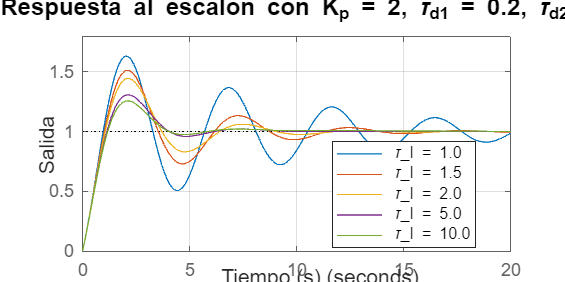

% PID_analisis_Kp.m
close all;
clear;
clc;

% Parámetros del sistema
K = 1;
p = 1;
Kp = 2;
tau_d1 = 0.2;
tau_d2 = 0.2;
tau_d = tau_d1 + tau_d2;
t = 0:0.1:20;

% Valores de tau_I a analizar
taui_vals = [1, 1.5, 2, 5, 10];

% Figura 1: respuesta al escalón
fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 10]);
hold on;

for i = 1:length(taui_vals)
    tau_i = taui_vals(i);
    
    % Numerador del PID
    num_PID = K*Kp*tau_d * [1, 1/tau_d, 1/(tau_d*tau_i)];
    
    % Denominador: suma de s^2*(s+p) y controlador
    den_planta = conv([1 0 0], [1 p]);
    den_control = K*Kp*tau_d1 * [1, 1/tau_d1, 1/(tau_d1*tau_i)];

    % Igualar tamaños
    n1 = length(den_planta);
    n2 = length(den_control);
    if n1 > n2
        den_control = [zeros(1, n1 - n2), den_control];
    else
        den_planta = [zeros(1, n2 - n1), den_planta];
    end
    den_PID = den_planta + den_control;

    % Sistema en lazo cerrado
    sys = tf(num_PID, den_PID);
    step(sys, t);

    % Métricas del transitorio
    [y, t_out] = step(sys, t);
    info = stepinfo(y, t_out, 'SettlingTimeThreshold', 0.02);
end

% Estética gráfica 1
title(['Respuesta al escalón con K_p = ' num2str(Kp) ', \tau_{d1} = ' num2str(tau_d1) ', \tau_{d2} = ' num2str(tau_d2)], 'FontSize', 16);
xlabel('Tiempo (s)', 'FontSize', 14);
ylabel('Salida', 'FontSize', 14);
legend(arrayfun(@(k) sprintf(' \\tau_{I} = %.1f', k), taui_vals, 'UniformOutput', false), 'Location', 'best', 'Interpreter', 'tex');
grid on;
set(gca, 'FontSize', 12);

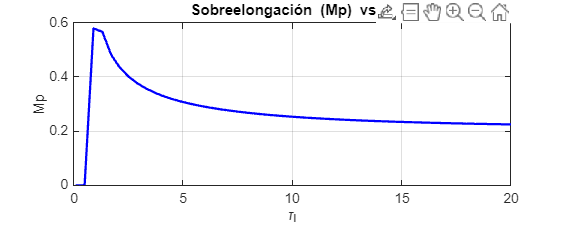



% Barrido de tau_I
taui_vals = linspace(0.1, 20, 50);
% Inicializar métricas
Mp = zeros(size(taui_vals));
Ts = zeros(size(taui_vals));
Tr = zeros(size(taui_vals));
Tp = zeros(size(taui_vals));

for i = 1:length(taui_vals)
    tau_i = taui_vals(i);

    % Numerador: KKp*tau_d * (s^2 + s/tau_d + 1/(tau_d*tau_i))
    num_PID = K * Kp * tau_d * [1, 1/tau_d, 1/(tau_d * tau_i)];

    % Denominador: s^2*(s + p) + controlador
    den_planta = conv([1 0 0], [1 p]);
    den_control = K * Kp * tau_d1 * [1, 1/tau_d1, 1/(tau_d1 * tau_i)];

    % Igualar tamaños antes de sumar
    n1 = length(den_planta);
    n2 = length(den_control);
    if n1 > n2
        den_control = [zeros(1, n1 - n2), den_control];
    else
        den_planta = [zeros(1, n2 - n1), den_planta];
    end
    den_PID = den_planta + den_control;

    % Sistema en lazo cerrado
    sys = tf(num_PID, den_PID);

    % Obtener métricas
    [y, t_out] = step(sys, t);
    info = stepinfo(y, t_out, 'SettlingTimeThreshold', 0.02);
    Mp(i) = info.Overshoot/100;
    Ts(i) = info.SettlingTime;
    Tr(i) = info.RiseTime;
    Tp(i) = info.PeakTime;
end

% === Gráfica: Mp vs tau_i ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Mp, 'b', 'LineWidth', 1.5);
xlabel('\tau_I'); ylabel('Mp');
title('Sobreelongación (Mp) vs \tau_I'); grid on;

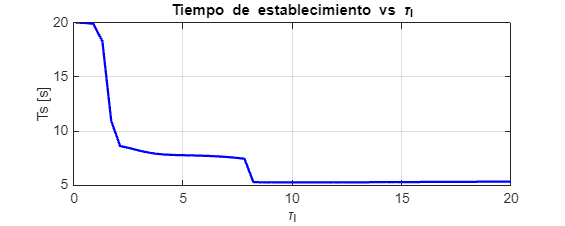


% === Gráfica: Ts vs tau_i ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Ts, 'b', 'LineWidth', 1.5);
xlabel('\tau_I'); ylabel('Ts [s]');
title('Tiempo de establecimiento vs \tau_I'); grid on;

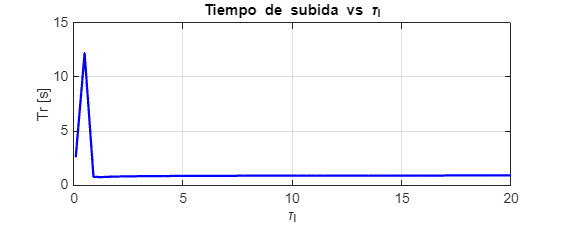


% === Gráfica: Tr vs tau_i ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Tr, 'b', 'LineWidth', 1.5);
xlabel('\tau_I'); ylabel('Tr [s]');
title('Tiempo de subida vs \tau_I'); grid on;

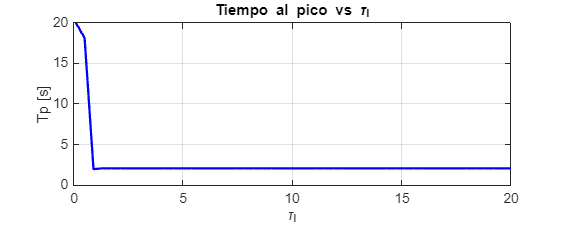


% === Gráfica: Tp vs tau_i ===
figure('Units', 'centimeters', 'Position', [2, 2, 20, 8]);
plot(taui_vals, Tp, 'b', 'LineWidth', 1.5);
xlabel('\tau_I'); ylabel('Tp [s]');
title('Tiempo al pico vs \tau_I'); grid on;